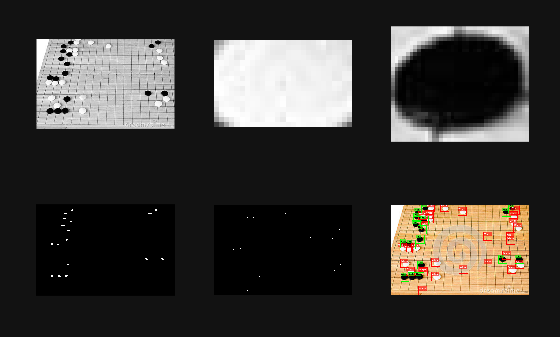

clc;
clear;
RGB_Go_Board = imread('Images/Go_Board.png');
Gray_Go_Board  = im2gray(RGB_Go_Board);

x= 178;
y= 145;
Gray_Black_Piece = Gray_Go_Board(y-15:y+15,x-18:x+18);


x= 225;
y= 65;
Gray_White_Piece = Gray_Go_Board(y-8:y+8,x-14:x+12);


A = normxcorr2(Gray_Black_Piece,Gray_Go_Board);
B = normxcorr2(Gray_White_Piece,Gray_Go_Board);


tiledlayout(2, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
nexttile;
imshow(Gray_Go_Board)
nexttile;
imshow(Gray_White_Piece)
nexttile;
imshow(Gray_Black_Piece)
nexttile;
imshow(A>0.55)
nexttile;
imshow(B>0.5)
nexttile;

B = (B>0.5);
stats = regionprops(B, 'Centroid');
centroids = cat(1, stats.Centroid);
squareSize = 50; 
x = centroids(:,1) - squareSize/2 + -15;
y = centroids(:,2) - squareSize/2 + -15;
bbox = [x y squareSize*ones(size(x)) squareSize*ones(size(y))];
outputImage = insertShape(RGB_Go_Board, 'Rectangle', bbox, 'Color', 'red', 'LineWidth', 2);
pos = [bbox(:,1), bbox(:,2)];   
labels = "White";
outputImage = insertText(outputImage, pos, labels, ...
    'FontSize', 14, 'BoxColor', 'red', 'TextColor', 'white', 'BoxOpacity', 0.6);

A = (A>0.55);
stats = regionprops(A, 'Centroid');
centroids = cat(1, stats.Centroid);
squareSize = 50; 
x = centroids(:,1) - squareSize/2 + -15;
y = centroids(:,2) - squareSize/2 + -15;
bbox = [x y squareSize*ones(size(x)) squareSize*ones(size(y))];
outputImage = insertShape(outputImage, 'Rectangle', bbox, 'Color', 'green', 'LineWidth', 2);
pos = [bbox(:,1), bbox(:,2)];   
labels = "Black";
outputImage = insertText(outputImage, pos, labels, ...
    'FontSize', 10, 'BoxColor', 'green', 'TextColor', 'black', 'BoxOpacity', 0.6);

imshow(outputImage);

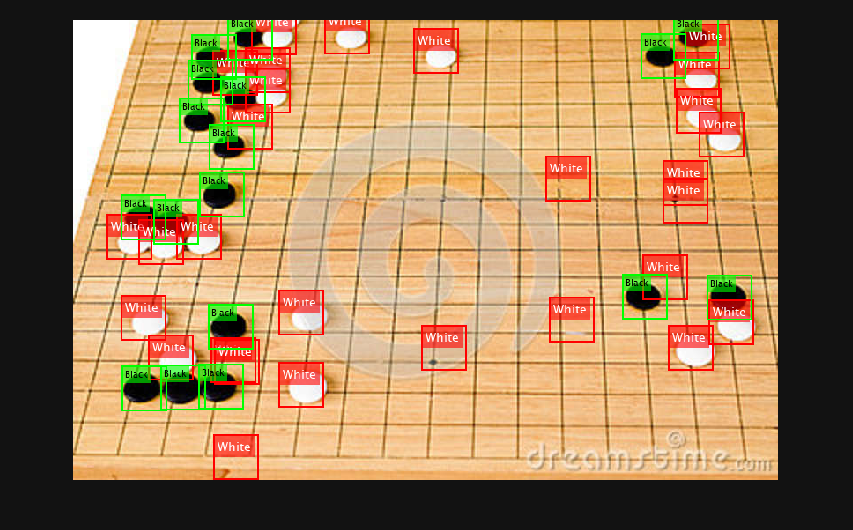

figure
imshow(outputImage);